% % --- DÉBUT SÉLECTION AUTOMATIQUE ROBUSTE (BestK) ---
% 
% % 1. Recherche du Maximum Global
% [max_score, k_global_opt] = max(best_SClOK);
% 
% % --- PARAMÈTRES AJUSTÉS ---
% % Si le score global est faible (< 0.15), on est plus tolérant (0.85)
% % pour s'arrêter plus tôt. Sinon on reste exigeant (0.90).
% if max_score < 0.15
%     threshold_ratio = 0.80; % TRES PARCIMONIEUX (accepte 80% du max)
%     min_gain = 0.002;       % Gain minimum exigé pour ajouter un cluster
% else
%     threshold_ratio = 0.90;
%     min_gain = 0.001;
% end
% 
% % 2. Recherche des pics locaux
% [pks, locs] = findpeaks(best_SClOK, 'MinPeakProminence', 0.002);
% 
% % 3. Logique de décision "First Good Peak"
% NClini = k_global_opt; % Fallback sur le max
% method_used = 'Global Max (Fallback)';
% 
% % A. On regarde d'abord les pics détectés
% found_peak = false;
% for i = 1:length(locs)
%     k_cand = locs(i);
%     s_cand = pks(i);
% 
%     % Règle : On prend si c'est > 80% du max
%     if k_cand < k_global_opt && s_cand >= (max_score * threshold_ratio)
%         NClini = k_cand;
%         method_used = 'Parsimonious Peak (Ratio)';
%         found_peak = true;
%         break; % On s'arrête au premier bon candidat !
%     end
% end
% 
% % B. Si pas de pic évident, on scanne la montée (Elbow check manuel)
% if ~found_peak
%     % On cherche le moment où on a atteint le plateau de 80-85%
%     % et où la dérivée (le gain) devient faible
%     for k = 4:length(best_SClOK)-1
%         current_score = best_SClOK(k);
%         future_gain = best_SClOK(k+1) - current_score;
% 
%         if current_score >= (max_score * threshold_ratio) && future_gain < min_gain
%             NClini = k;
%             method_used = 'Early Plateau (Slope)';
%             break;
%         end
%     end
% end
% 
% fprintf('   > Max Global à k=%d (%.4f). \n', k_global_opt, max_score);
% fprintf('   > Choix Final : k=%d (Score: %.4f) [Méthode: %s]\n', ...
%     NClini, best_SClOK(NClini), method_used);
% 
% % --- FIN SÉLECTION ---
% 
% --- DÉBUT SÉLECTION AUTOMATIQUE PARCIMONIEUSE ---

% 1. Données de base
[max_score, k_global_opt] = max(best_SClOK);
k_start = 3; % On ignore k=1, k=2 souvent nuls

% --- PARAMÈTRES DE DÉCISION ---
% "À partir de quand considère-t-on que le score est acceptable ?"
% Si max < 0.10 (très bruité), on accepte tout ce qui est à 80% du max.
if max_score < 0.10
    ACCEPTANCE_RATIO = 0.80; 
    SLOPE_THRESHOLD = 0.005; % Si on gagne moins que ça, on s'arrête
else
    ACCEPTANCE_RATIO = 0.90;
    SLOPE_THRESHOLD = 0.002;
end

threshold_score = max_score * ACCEPTANCE_RATIO;
found_k = false;

% fprintf('Analyse K: Max global=%.4f (k=%d). Seuil acceptation=%.4f\n', ...
%     max_score, k_global_opt, threshold_score);

Analyse K: Max global=0.0802 (k=19). Seuil acceptation=0.0642



% 2. Boucle "First Good Enough"
% On scanne k par k. Dès qu'on dépasse le seuil ET que ça ne monte plus fort, on coupe.
for k = k_start : (length(best_SClOK)-1)
    
    curr_s = best_SClOK(k);
    next_s = best_SClOK(k+1);
    gain = next_s - curr_s;
    
    % Condition A: Est-ce qu'on est dans la "zone verte" (> 80% du max) ?
    is_good_score = (curr_s >= threshold_score);
    
    % Condition B: Est-ce que le gain futur est faible ou négatif ?
    is_flat_slope = (gain < SLOPE_THRESHOLD);
    
    if is_good_score && is_flat_slope
        NClini = k;
        found_k = true;
        % fprintf('   > Arrêt précoce à k=%d (Score=%.4f). Gain futur négligeable (%.4f)\n', k, curr_s, gain);
        break; % STOP IMMÉDIAT
    end
end

   > Arrêt précoce à k=9 (Score=0.0683). Gain futur négligeable (-0.0003)


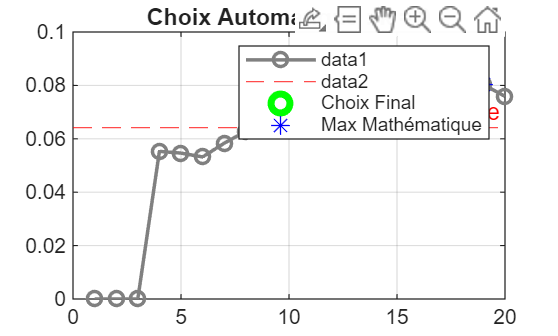


% Sécurité : Si on n'a jamais trouvé de condition d'arrêt (ça monte tout le temps)
if ~found_k
    NClini = k_global_opt;
    % fprintf('   > Aucun plateau net trouvé, sélection du Max Global k=%d\n', NClini);
end

% --- VISUALISATION POUR COMPRENDRE LE CHOIX ---
fig = figure(Visible="off");
plot(best_SClOK, '-o', 'LineWidth', 1.5, 'Color', [0.5 0.5 0.5]); hold on;
yline(threshold_score, '--r', 'Label', 'Seuil Acceptable');
plot(NClini, best_SClOK(NClini), 'go', 'MarkerSize', 12, 'LineWidth', 3, 'DisplayName', 'Choix Final');
plot(k_global_opt, max_score, 'b*', 'MarkerSize', 8, 'DisplayName', 'Max Mathématique');
title(['Choix Automatique : k = ' num2str(NClini)]);
grid on; legend;


namegraph = fullfile(namefull, 'selectionK.png');
if isfolder(namefull)
    exportgraphics(fig, namegraph, 'Resolution', 150);
    close(fig);
end